# Torsión en barras con perfiles cuadriculados

clc
clear all %#ok<*CLALL>
PYTHON_EXEC="python.exe";
profiles_dir = "perfiles";
profile_files = get_profile_files(profiles_dir);
 

**Crear nuevo perfil**

new_profile_name = sprintf("%s","ishape");
ncells = 10;
if ~exist(profiles_dir, 'dir')
   mkdir(profiles_dir)
end
output = sprintf("%s/%s", profiles_dir, new_profile_name);
system(sprintf("%s profile_designer.py %s %d", PYTHON_EXEC, output, ncells));

Perfil guardado en perfiles/ishape.ppm 


if ~contains(profile_files, new_profile_name)
    profile_files(end+1) = new_profile_name;
end
 

**Seleccionar perfil**

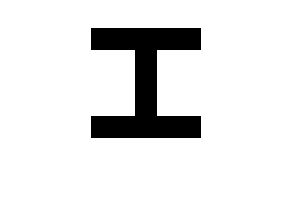

profile_name = profile_files(2);
profile_file = sprintf("%s/%s", profiles_dir, profile_name);
profile_img = imread(profile_file);
imshow(imresize(profile_img, 10, "nearest"))

function profile_files = get_profile_files(profiles_dir)
    profile_files = struct2cell(dir(sprintf("%s/*.ppm",profiles_dir)));
    profile_files = string(profile_files(1,:));
end